% rn_sl.mlx.m
% This is program generate red noise from the sequence of white noise
% Priya 29/12/22
% reference: https://atmos.washington.edu/~breth/classes/AM582/lect/lect8-notes.pdf
%correction in rn assigning 02/01/23
%labels assigned 03/01/23

lseq = 10000;
filename = 'wn_fromsimulink';
load wn_fromsimulink;
wn2 = out.simout.Data;
rn = zeros(lseq,1);
rn(1)=wn2(1);
rcc = 0.5

rcc = 0.5000

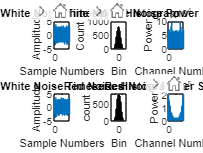


% generate red noise from the above white noise

for idx = 2:lseq
     rn(idx,1)=rcc*rn(idx-1,1)+(1-rcc^2)^(0.5)*wn2(idx,1); 
end

% plotting the white and red noises01
subplot(2,3,1)
plot(wn2);
title('White Noise Timeseries');
xlabel('Sample Numbers');
ylabel('Amplitude'); 

subplot(2,3,2)
histogram(wn2);
title('White Noise Histogram');
xlabel('Bin');
ylabel('Count');

subplot(2,3,3)
swn = abs(fft(wn2));
pwn = swn.^2;
plot(pwn);
title('White Noise Power Spectrum');
xlabel('Channel Number');
ylabel('Power');

subplot(2,3,4);
plot(rn);
title('White Noise Timeseries');
xlabel('Sample Numbers');
ylabel('Amplitude');

subplot(2,3,5);
histogram(rn);
title('Red Noise Histogram');
xlabel('Bin');
ylabel('count');

subplot(2,3,6);
srn = abs(fft(rn));
prn = srn.^2;
plot(prn);
title('Red Noise Power Spectrum');
xlabel('Channel Number');
ylabel('Power');